clear;
% f = 0.01034409; % friction coef for aerohockey table
f = 1;

%puck geometry
h = 0.45;
r = 1;

% components of motion laws when type D trajectory
delta = 2 .* f .* h / r;
phi_0 = 0.975 + (0.992 - 0.975) .* delta;

[p_a_res, p_b_res, p_a_hat_res, p_c_hat_res, p_c_res] = ...
	calculate_integrals(r);

p_d = @(phi) (1 - delta.^2 .* sin(phi).^2 .* ...
	p_b_res(fix(phi/0.01)+1) .* p_c_res(fix(phi/0.01)+1));

p_omega =@(phi) 2.*(p_a_hat_res(fix(phi/0.01)+1) + ...
	(delta.^2 * cos(phi).^2 .* p_a_res(fix(phi/0.01)+1) ...
	.* p_b_res(fix(phi/0.01)+1) .* p_c_hat_res(fix(phi/0.01)+1) ...
	./ p_d_res(fix(phi/0.01)+1)));
p_orth = @(phi) delta .* p_a_res(fix(phi/0.01)+1) .* p_b_res(fix(phi/0.01)+1) ...
	./ p_d_res(fix(phi/0.01)+1);

p_d_res = [];
p_parall_res = [];
p_omega_res = [];
p_orth_res = [];
for phi = 0:0.01:pi/2
	p_d_res = [p_d_res; p_d(phi)];
end
p_parall =@(phi) p_a_res(fix(phi/0.01)+1) ./ p_d_res(fix(phi/0.01)+1);

for phi = 0:0.01:pi/2
	p_parall_res = [p_parall_res; p_parall(phi)];
	p_omega_res = [p_omega_res; p_omega(phi)];
	p_orth_res = [p_orth_res; p_orth(phi)];
end


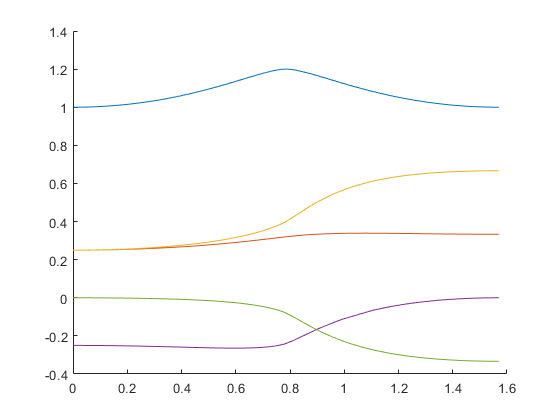

% clf(1);
figure(1);
hold on
phi = 0:0.01:pi/2;
plot(phi, p_a_res);
plot(phi, p_b_res);
plot(phi, p_a_hat_res);
plot(phi, p_c_hat_res);
plot(phi, p_c_res);
% plot(phi, p_d_res)
% plot(phi, p_parall_res);
% plot(phi, p_omega_res);
% plot(phi, p_orth_res);
hold off

v_0 = 10; % m/s
% v_x0 = v_0 * cos(psi_0);
% v_y0 = v_0 * sin(psi_0);
phi_0 = 0.975 + (0.992 - 0.975) * delta;
w_0 = tan(phi_0) * v_0 / r; % rad/s

phi_start = atan(r * w_0 / v_0);
Q_0 = v_0 / cos(phi_start);

g = 9.80665;
J = f * g;
d_t = 0.01;
t_sim = 10; % [s]
sim_steps = round(t_sim / d_t);



Q_dot =@(phi) -(cos(phi).^2 .* p_parall_res(fix(phi/0.01)+1) ...
	+ (sin(phi)).^2 .* p_omega_res(fix(phi/0.01)+1))* J;
%find all Q
Q = [Q_0];
for step = 1:sim_steps
	Q_prev = Q(end);
	Q_next = Q_prev + Q_dot(phi_start) * d_t;
	if Q_next < 0
		break
	end
	Q = [Q ; Q_next];
end

%find all psi
psi_dot =@(phi) -sin(phi) .* p_orth_res(fix(phi/0.01)+1) .* J;
psi_0 = (pi/180) * (41.4);
psi = psi_0;
for step = 1:sim_steps
% 	Q_prev = Q(end);
	psi_next = psi(end) + psi_dot(phi_start) * d_t;
	if psi_next < 0
		break
	end
	psi = [psi ; psi_next];
end

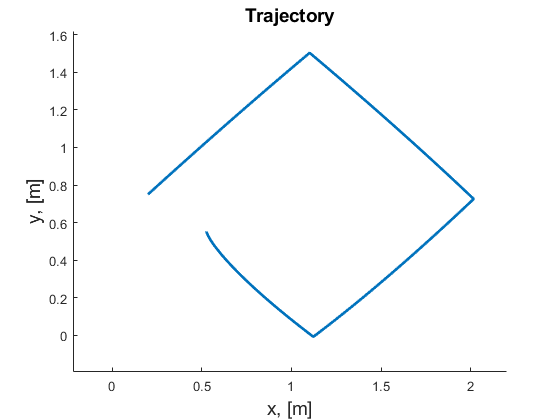

%integral functions
Q_dot =@(phi) -(cos(phi).^2 .* p_parall_res(fix(phi/0.01)+1) ...
	+ (sin(phi)).^2 .* p_omega_res(fix(phi/0.01)+1))* J;

psi_dot =@(phi) -sin(phi) .* p_orth_res(fix(phi/0.01)+1) .* J;

phi_dot =@(phi) sin(phi) .* cos(phi) .* (p_parall_res(fix(phi/0.01)+1) ...
	- p_omega_res(fix(phi/0.01)+1)) .* J;

% physical parameters
width_table = 1.5; %[m]
length_table = 2; %[m]
t = 0;
x_0 = length_table/10; % [m]
y_0 = width_table/2; % [m]

v_0 = 30; % m/s
psi_0 = (pi/180) * (41); % [rad] angle to x-axis
v_x0 = v_0 * cos(psi_0);
v_y0 = v_0 * sin(psi_0);



% w_0 = tan(phi_0) * v_0 / r; % rad/s
w_0 = 100;

phi_start = atan(r*w_0/v_0);

% X_vec = zeros(4, sim_steps);
X_vec(:, 1) = [x_0, y_0, v_x0, v_y0].'; 

%simulation ideal system trajectory
Q = Q_0;
psi = psi_0;
phi = phi_start;
for step = 1:sim_steps-1
	phi_next = phi(end) + phi_dot(phi(end))/Q(end) * d_t;
	
	Q_next = Q(end) + Q_dot(phi_next) * d_t;
	
	%stop if v < 0 (Q < 0)
	if Q_next < 0
		break
	end
	
	psi_next = psi(end) + psi_dot(phi_next)/Q_next * d_t;
	
	v_x = Q_next .* cos(phi_next) .* cos(psi_next);
	v_y = Q_next .* cos(phi_next) .* sin(psi_next);
	
	x = X_vec(1, step) + v_x * d_t;
	y = X_vec(2, step) + v_y * d_t;
	
	X_vec(:, step + 1) = [x; y; v_x; v_y];
	
	% bounce off the X walls
	if x > length_table || x < 0
		psi_next = pi - psi_next;
	end
	% bounce off the Y walls
	if y > width_table || y < 0
		psi_next = -psi_next;
	end
	psi = [psi; psi_next];
	Q = [Q; Q_next];
	phi = [phi; phi_next];

end
%plot ideal system
clf();
figure()
hold on
% subplot(2,1,1);
plot(X_vec(1,:), X_vec(2,:), 'LineWidth', 2);
axis([0, length_table, 0, width_table])
title('Trajectory', 'FontSize', 14)
xlabel('x, [m]', 'FontSize', 14)
ylabel('y, [m]', 'FontSize', 14)
hold off

function list = clean_data(data)
	list = data;
	prev_idx = 0;
	next_idx = 0;
	for ii = 1:length(list)
		if isinf(list(ii)) || isnan(list(ii))
			prev_idx = ii-1;
			for jj = ii:length(list)
				if ~(isinf(list(jj)) || isnan(list(jj)))
					next_idx = jj;
					break
				end
			end
		end
		for kk = 1:(next_idx - prev_idx)
			derivative = (list(next_idx) - list(prev_idx)) / (next_idx - prev_idx);
			list(prev_idx+kk) = list(prev_idx) + kk * derivative;
		end
		ii = next_idx;
	end
end


function [p_a_res, p_b_res, p_a_hat_res, p_c_hat_res, p_c_res] = ...
	calculate_integrals(r)
	% calculates values for p_a, p_b, p_a_hat, p_c_hat, p_c 
	% for phi on [0; pi/2]
	p_a = @(phi) real(integral2(@(ro, nu) ...
		(cos(phi) - sin(phi) .* (ro/r) .* sin(nu)).^2 .* ro ./(pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
		0, r, 0, 2*pi));
	p_b = @(phi) real(integral2(@(ro, nu) ...
		((ro/r) .* cos(nu)).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(1/2)),...
		0, r, 0, 2*pi));
	p_a_hat = @(phi) real(integral2(@(ro, nu) ...
		( (sin(phi) .* (ro/r) - cos(phi) .* sin(nu)).^2) .*(ro/r).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
		0, r, 0, 2*pi));
	p_c_hat = @(phi) real(integral2(@(ro, nu) ...
		(sin(phi).^2 .* (ro/r).^2 .* cos(2*nu) + 2 .* cos(phi) .* sin(phi) .* (ro/r) .* sin(nu).^3 - cos(phi).^2 .* sin(nu).^2) .*(ro/r).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
		0, r, 0, 2*pi));
	p_c =@(phi) p_b(phi) - p_a_hat(phi);


	
	p_a_res = [];
	p_b_res = [];
	p_a_hat_res = [];
	p_c_hat_res = [];
	p_c_res = [];
	p_d_res = [];
	for phi = 0:0.01:pi/2
		p_a_data = p_a(phi);
		p_b_data = p_b(phi);
		p_a_hat_data = p_a_hat(phi);
		p_c_hat_data = p_c_hat(phi);
		p_c_data = p_c(phi);
		p_a_res = [p_a_res; real(p_a_data)];
		p_b_res = [p_b_res; real(p_b_data)];
		p_a_hat_res = [p_a_hat_res; real(p_a_hat_data)];
		p_c_hat_res = [p_c_hat_res; real(p_c_hat_data)];
		p_c_res = [p_c_res; real(p_c_data)];	

	end
	p_a_res = clean_data(p_a_res);
	p_b_res = clean_data(p_b_res);
	p_a_hat_res = clean_data(p_a_hat_res);
	p_c_hat_res = clean_data(p_c_hat_res);
	p_c_res = clean_data(p_c_res);
end